# TAIM 2

Add the floder to the path:

addpath("letterFiles/");

Read a letter:

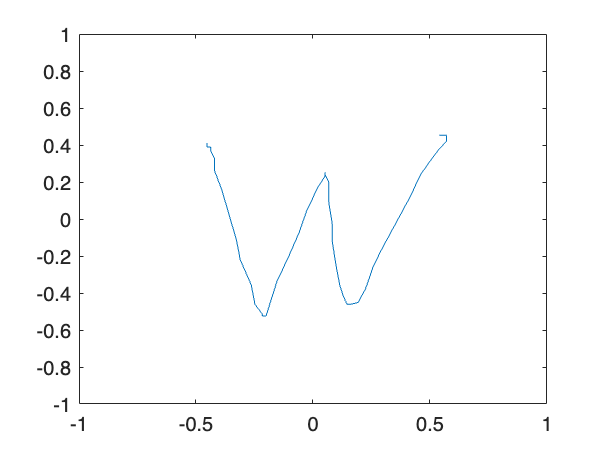

letter = readtable("user016_w_1.txt");
plot(letter.X, letter.Y);
axis([-1 1 -1 1]);

## Create a Datastore

letterds = datastore("letterFiles/*_r_*.txt");

## Read Letters

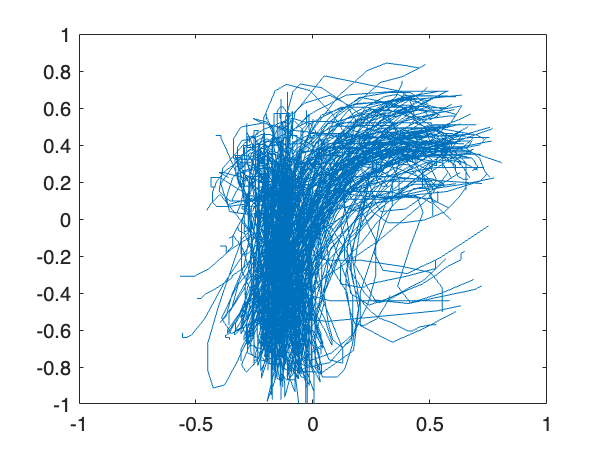

%data = read(letterds); % Read one letter
data = readall(letterds); % Read all letters
plot(data.X, data.Y);
axis([-1 1 -1 1]);

## Observations

timeToWrite = letter.Time(end);
letterHeight = range(letter.Y);
letterWidth = range(letter.X);
features = table(timeToWrite,letterHeight, letterWidth);

## Create a Datastore for all letters

letterds = datastore("letterFiles/*.txt");

## Transform Datastore

Used to apply a function to a datastore. In this case we are extracting the characteristics of all letters.

featds = transform(letterds,@extractLetterFeatures);
data = readall(featds);

## Labels

We need to group the letters together by type. We do this by labeling.

startPat="user"+wildcardPattern+"_";
c = extractBetween(letterds.Files,startPat,"_");
data.character = categorical(c);